 % PBS, 37C, ab40, pH 7.4
clc;
clear;
close all;
tic
% Change I0 to see the its effect on graph

tExp = 24*[0	1	2	3	4	5];
% ConcExp = [100	175	185	198	200	201]/5.74;
% errExp =   [10 10 10 8 9 10]/5.74;
% errCGA20NPExp =   [0 10 10 9 9 10]/5.74;
% ConcCGA20NPExp = [0 116 121 117 116 112]/5.74;
ConcCGA60all = [98.75417	144.95914	152.30114	156.9382	158.7599	162.45851]/5.74;
errExpCGA60all =   [10 10 10 8 9 10]/5.74;
ConcCGA60 = [98.75417	144.95914	152.30114	156.9382	158.7599	162.45851]/5.74;
errExpCGA60 =   [10 10 10 8 9 10]/5.74;
errExpCGA40 =   [10 10 10 8 9 10]/5.74;
errExpCGA20 =   [10 10 10 8 9 10]/5.74;

ConcCGA40 = [17.4 27.2 28.7 29.4 29.6 29.6];
ConcCGA20 = [17.5 29.0 29.5 30.6 31.3 31.6];
MW = .0043;      %(*1e6 Da)
% MW of chlorogenic acid (CGA), 354.31 g/mol
% 20 microg/ml of CGA = 56.45 microMolar
M0 = 35-17.4; f = 1; %(micro mol/L)
%I0 = 5.2; 
I0 = 5.2; %(micro mol/L) % can be reduced a bit more, bcoz radical still exists
% y0 = zeros(9,1); y0(1) = I0; y0(3) = M0;
y01 = zeros(10,1); y01(1) = I0; y01(3) = M0; y01(5)= 17.4;

% dose dependency sensitivity
dose = 40

dose =     40


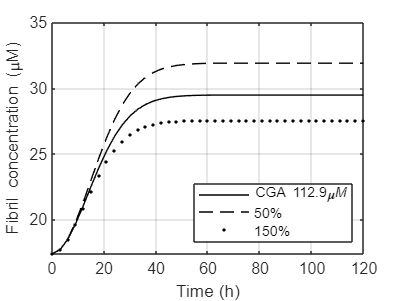


x1 =.5; x2 =1.5;

y01(10) = 2*56.45;
 

% Paper 1 para
kd = 0.000179282985463036;
ki = 1619460;
kp = 2.09716980428679;
ktc = 0.170721599476453;
ktd = 0;

%optimized 
ksc = 0;
kb = 0;
km = 0.000178127151239720;

k1 = [kd;ki;kp;ktc;ktd;ksc;kb;km];

%   tspan = [0 120];
tspan = 0:3:120;
   
%     options = odeset('AbsTol',1e1); 
    options1 = odeset('AbsTol',1e-7);
%     [t,y] = ode15s(@(t,y)M2substrate(t,y,k,f),tspan,y0,options);
    [t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);


plot(t1,y1(:,5)+y1(:,8),'Color','k');

    xlabel('Time (h)');
    ylabel('Fibril concentration (\muM)');
    %title('Live total conc')
    grid on
%      xlim([0 100])
hold on 


y01(10) = x1* 2*56.45;
[t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);

   plot(t1,y1(:,5)+y1(:,8),'--','Color','k');

    xlabel('Time (h)');
    ylabel('Fibril concentration (\muM)');

y01(10) = x2* 2*56.45;
[t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);

   plot(t1,y1(:,5)+y1(:,8),'.','Color','k','LineWidth',1);

    xlabel('Time (h)');
    ylabel('Fibril concentration (\muM)');
    xlim([0 120])
    ylim([17.4 35])
 legend('CGA 112.9\it{\mu}M','50%','150%','Location','southeast')

hold off

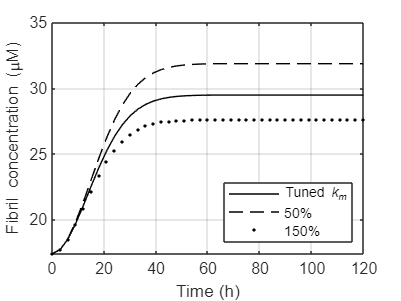


% sensitivity for km
% reset dose
y01(10) =  2*56.45;


[t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);

   plot(t1,y1(:,5)+y1(:,8),'Color','k');
   ylim([17.4 35])
hold on

k1(8) = x1*k1(8);
[t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);

   plot(t1,y1(:,5)+y1(:,8),'--','Color','k');
   ylim([17.4 35])

%     xlabel('Time (h)');
%     ylabel('Total fibril concentration (\muM)');

k1(8) = x2* k1(8)/x1;
[t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);

   plot(t1,y1(:,5)+y1(:,8),'.','Color','k');
   ylim([17.4 35])

    xlabel('Time (h)');
    ylabel('Fibril concentration (\muM)');
    xlim([0 120])
    ylim([17.4 35])
    grid on
 legend('Tuned \it{k_m}','50% ','150%','Location','southeast')

hold off

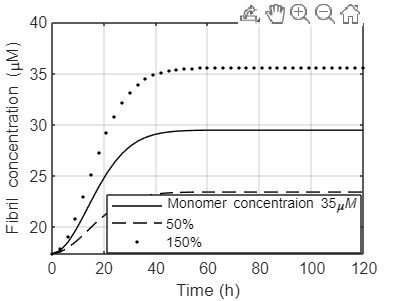


% sensitivity for initial monomer conc
% reset previous para
k1(8) = k1(8)/x2;


[t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);

   plot(t1,y1(:,5)+y1(:,8),'Color','k');
hold on

y01(3) = x1*y01(3);
[t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);

   plot(t1,y1(:,5)+y1(:,8),'--','Color','k');

%     xlabel('Time (h)');
%     ylabel('Total fibril concentration (\muM)');

y01(3) = x2* y01(3)/x1;
[t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);

   plot(t1,y1(:,5)+y1(:,8),'.','Color','k');

    xlabel('Time (h)');
    ylabel('Fibril concentration (\muM)');
    xlim([0 120])
    ylim([17.4 40])
    grid on
 legend('Monomer concentraion 35\it{\mu}M','50% ','150%','Location','southeast')

hold off

legend("Position",[0.30701,0.16472,0.58166,0.17557])

legend("Position",[0.26918,0.16039,0.6324,0.19087])





% [t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);
% plot(t1,y1(:,5)+y1(:,8),'Color','k');
% 
% hold on
% errorbar(tExp,ConcCGA40,errExpCGA40,'o','Color','k')

% y01(10) = 56.45;
%   [t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);
%   plot(t1,y1(:,5)+y1(:,8),'Color','k');
% 
%   
%     grid on
%     hold on
%     ylim([0 35])
% 
% errorbar(tExp,ConcCGA20,errExpCGA20,'s','Color','k')
% 
% y01(10) = 3*56.45;
%   [t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);
%   plot(t1,y1(:,5)+y1(:,8),'--','Color','k');
% 
%     xlabel('Time (h)');
%     ylabel('Total fibril concentration (\muM)');
%     grid on
% 
% errorbar(tExp,ConcCGA60,errExpCGA20,'d','Color','k')
% % legend('With 60 CGA','Experimental Data','Color','k')








% %Simulation
%     tspan = [0 120];
%    
% %     options = odeset('AbsTol',1e1); 
%     options1 = odeset('AbsTol',1e-7);
% %     [t,y] = ode15s(@(t,y)M2substrate(t,y,k,f),tspan,y0,options);
%     [t1,y1] = ode23s(@(t1,y1)M2substrateCGAScaDisCGAonly(t1,y1,k1,f),tspan,y01,options1);
% 
% 
% %Simulation
%     tspan = [0 100];
%     options = odeset('AbsTol',1e2);
% 
%  y0(3) = 280
% % Initiator concentration Sensitivity
%      I0 = 5.2, f = 1
%      y0(1) = I0;
%      [t,y] = ode15s(@(t,y)Momsubstrate(t,y,k0,f),tspan,y0,options);
% plot(t,y(:,5)+y(:,8),'Color','k');
%     xlabel('Time (h)');
%     ylabel('Total Fibril (\muM)');
%     grid on
% legend('Assumed')
%     hold on
% I0 = 0.5* 5.2
%      y0(1) = I0;
%      [t,y] = ode15s(@(t,y)Momsubstrate(t,y,k0,f),tspan,y0,options);
% plot(t,y(:,5)+y(:,8),'--','Color','k');
%     xlabel('Time (h)');
%     ylabel('Total Fibril (\muM)');
%     
% legend('50% ')
%     hold on
% I0 = 1.5* 5.2
%      y0(1) = I0;
%      [t,y] = ode15s(@(t,y)Momsubstrate(t,y,k0,f),tspan,y0,options);
% plot(t,y(:,5)+y(:,8),':','Color','k');
%     xlabel('Time (h)');
%     ylabel('Total Fibril (\muM)');
% %     title(' Initial Initiator Concentration Sensitivity')
% title('\it{I_0}')
%    legend('Assumed','50%','150% ','Location','southeast')
%     hold off
%     % Reset The Value of I0
%     I0 = 5.2
% % Initiator Efficiency Sensitivity
% 
% f = 1
%      y0(1) = I0;
%      [t,y] = ode15s(@(t,y)Momsubstrate(t,y,k0,f),tspan,y0,options);
% plot(t,y(:,5)+y(:,8),'Color','k');
%     xlabel('Time (h)');
%     ylabel('Total Fibril (\muM)');
%     title('Initiator Efficiency Sensitivity')
%    hold on
% 
% f = .75;
%      
%      [t,y] = ode15s(@(t,y)Momsubstrate(t,y,k0,f),tspan,y0,options);
% plot(t,y(:,5)+y(:,8),':','Color','k');
%     xlabel('Time (h)');
%     ylabel('Total Fibril (\muM)');
%     title('Initiator Efficiency Sensitivity')
%     hold on
% f = .50;
%    
%      [t,y] = ode15s(@(t,y)Momsubstrate(t,y,k0,f),tspan,y0,options);
% plot(t,y(:,5)+y(:,8),'--','Color','k');
%     xlabel('Time (h)');
%     ylabel('Total Fibril (\muM)');
%     title('\itf')
%    legend('Assumed','75%','50%','Location','southeast')
% grid on
%    hold off
% % Reset The Value of f
%    f=1
%    
% % Rate Parameters Sensitivity
% for i = 1:1:4
%  i
%  l = 1
%    for j = [1 0.5 1.5]   
%        j
%        linS = ["-","--",":"];
%     k0(i) = j*k0(i)
%      [t,y] = ode15s(@(t,y)Momsubstrate(t,y,k0,f),tspan,y0,options);
%    k0(i) = k0(i)/j
% plot(t,y(:,5)+y(:,8),linS(l),'Color','k');
%     xlabel('Time (h)');
%     ylabel('Total Fibril (\muM)');
%     grid on
%     xlim([0 100])
%     hold on
%      l = l+1
%    end
%    legend('Tuned','50% ','150%','Location','southeast')
%    set_title = ["\it{k_d}","\it{k_i}","\it{k_p}","\it{k_{tc}}"];
%    title( set_title (i))
% 
%    hold off
%    figure
% end
% % Ktd Sensitivity 
% tspan1 = [0 400]
%      k0(5) = 0
%      [t,y] = ode15s(@(t,y)Momsubstrate(t,y,k0,f),tspan1,y0,options);
% plot(t,y(:,5)+y(:,8),"-",'Color','k');
% hold on
% 
%     k0(5) = 10
%      [t,y] = ode15s(@(t,y)Momsubstrate(t,y,k0,f),tspan1,y0,options);
% plot(t,y(:,5)+y(:,8),"--",'Color','k');
% hold on
%     k0(5) = 50
%      [t,y] = ode15s(@(t,y)Momsubstrate(t,y,k0,f),tspan1,y0,options);
% plot(t,y(:,5)+y(:,8),":",'Color','k');
% hold on 
% 
%     xlabel('Time (h)');
%     ylabel('Total Fibril (\muM)');
%     grid on
%     xlim([0 400])
%     hold off
%  %Reset
%  k0(5) = 0
%    legend('Tuned (\it{k_{td}} \approx 0)','\it{k_{td}} = 10 ','\it{k_{td}} = 100','Location','southeast')
%    title( "\it{k_{td}}")
% 
% 
% % Initial Monomer Concentration
%     tspan = [0 100];
% M0 = 280; f = 1
%  y0(3) = M0
% [t,y] = ode15s(@(t,y)Momsubstrate(t,y,k0,f),tspan,y0,options);
% plot(t,y(:,5)+y(:,8),'-','Color','k');
%  title( "\it{M_0}")
% % legend('Monomer at 280 \muM')
% grid on
% hold on
% M0 = .5*280
%  y0(3) = M0
% [t,y] = ode15s(@(t,y)Momsubstrate(t,y,k0,f),tspan,y0,options);
% plot(t,y(:,5)+y(:,8),'--','Color','k');
% % legend('50%')
% hold on
% M0 = 1.5*280
%  y0(3) = M0
% [t,y] = ode23s(@(t,y)Momsubstrate(t,y,k0,f),tspan,y0,options);
% plot(t,y(:,5)+y(:,8),':','Color','k');
% legend('280 \muM','50%','150%','Location','southeast')
% hold off
%  xlabel('Time (h)');
%  ylabel('Total Fibril (\muM)');
% 
% legend("Position",[0.63586,0.16747,0.25779,0.18939])
% 
% M0 = 280
%  y0(3) = M0